%% MATLAB Script for Bode Diagram and Break Frequency Analysis

% Define the transfer function G(s)
numerator = 5425.7 * [1 0.2];  % Numerator: 5425.7(s + 0.2)
denominator = conv([1 12], [1 12]);  % (s + 12)^2
denominator = conv(denominator, [2 3]);  % Multiply with (2s + 3)

% Create the transfer function
G = tf(numerator, denominator);

% Display the transfer function
disp('Transfer Function G(s):');

Transfer Function G(s):


G

G =
 
         5426 s + 1085
  ----------------------------
  2 s^3 + 51 s^2 + 360 s + 432
 
Continuous-time transfer function.
Model Properties



%% Calculate and display DC gain
DC_gain = dcgain(G);
DC_gain_dB = 20 * log10(DC_gain);
fprintf('DC Gain: %.2f (linear) or %.2f dB\n', DC_gain, DC_gain_dB);

DC Gain: 2.51 (linear) or 8.00 dB


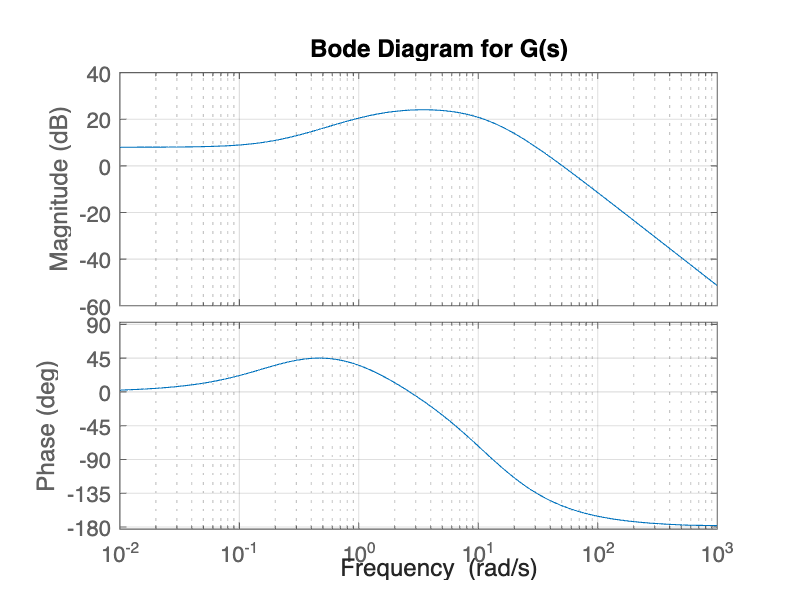


%% Bode plot
figure;
bode(G);
grid on;
title('Bode Diagram for G(s)');


%% Identify break frequencies
% Poles and zeros
[poles, zeros] = pzmap(G);
fprintf('Poles: \n');

Poles: 


disp(poles);

 -12.0000 + 0.0000i
 -12.0000 - 0.0000i
  -1.5000 + 0.0000i



fprintf('Zeros: \n');

Zeros: 


disp(zeros);

   -0.2000




% Calculate and display break frequencies
break_frequencies = abs([poles; zeros]);
fprintf('Break Frequencies (rad/s):\n');

Break Frequencies (rad/s):


disp(break_frequencies);

   12.0000
   12.0000
    1.5000
    0.2000



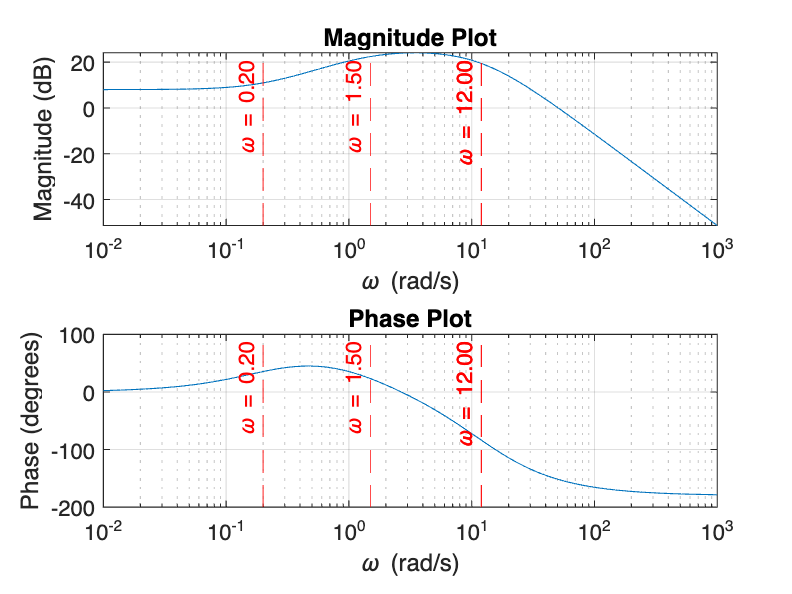


% Highlight break frequencies on Bode plot
figure;
[mag, phase, omega] = bode(G);
mag = squeeze(mag);
phase = squeeze(phase);
omega = squeeze(omega);

% Plot magnitude
subplot(2, 1, 1);
semilogx(omega, 20 * log10(mag));
grid on;
hold on;
for w = break_frequencies'
    xline(w, '--r', sprintf('\\omega = %.2f', w), 'LabelHorizontalAlignment', 'left');
end
title('Magnitude Plot');
xlabel('\omega (rad/s)');
ylabel('Magnitude (dB)');

% Plot phase
subplot(2, 1, 2);
semilogx(omega, phase);
grid on;
hold on;
for w = break_frequencies'
    xline(w, '--r', sprintf('\\omega = %.2f', w), 'LabelHorizontalAlignment', 'left');
end
title('Phase Plot');
xlabel('\omega (rad/s)');
ylabel('Phase (degrees)');